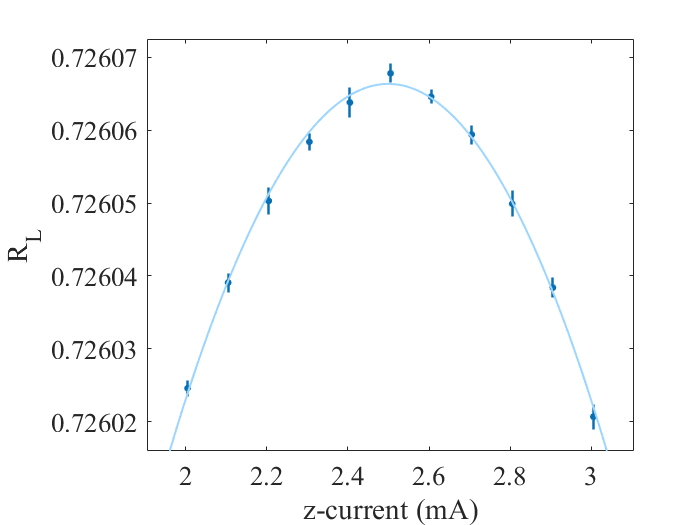


close all;
clear all;

maindir = ['\\Artemis-pc\Data\2026-10-23\' ...
    'xFit_far'];
save_data = 0;

xc_approx = 2500*1e-3;
x = 1e-3*([2005 2105 ...
    2205 2305 2405 ...
    2505 2605 2705 ...
    2805 2905 3005]);
%% far 3987 %%
y = [0.7260246 0.7260391 ...
    0.7260503 0.7260584 0.7260638 ...
    0.7260678 0.7260646 0.7260594 ...
    0.7260499 0.7260384 0.7260207];
err = 1e-7*[11 13 ...
    18 12 20 ...
    13 10 13 ...
    18 14 17];

%% near 3995 %%
% y = [0.7260187 ...
%     0.7260404 0.7260562 0.7260640 ...
%     0.7260680 0.7260622 0.7260529 ...
%     0.7260417 0.7260189];
% err = 1e-7*[16 ...
%     13 15 18 ...
%     12 14 19 ...
%     25 17];

w = 1./err.^2;

f1 = figure; hold on;
errorbar(x,y,err,'.','CapSize',0,...
    'MarkerSize',14,'LineWidth',1.5,...
    'Color',[0.04,0.44,0.71]);

margin_per = 0.1;

xmin = min(x)-margin_per*(max(x)-min(x));
xmax = max(x)+margin_per*(max(x)-min(x));

ymin = min(y)-margin_per*(max(y)-min(y));
ymax = max(y)+margin_per*(max(y)-min(y));

xlim([xmin xmax]);
ylim([ymin ymax]);

set(gcf,'Visible','on');

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData( x, y, w );

% 设置 fittype 和选项。
ft = fittype( 'a*(x-x0)^2+R0', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.726 0 xc_approx];
opts.Weights = weights;

% 对数据进行模型拟合。
[fitted, gof] = fit( xData, yData, ft, opts );
interval = confint(fitted);
a = fitted.a;
a_err = abs(interval(1,2)-interval(2,2))/4;
R0 = fitted.R0;
R0_err = abs(interval(1,1)-interval(2,1))/4;
x0 = fitted.x0;
x0_err = abs(interval(1,3)-interval(2,3))/4;

% 绘制数据拟合图。
l = plot(fitted);
l.LineWidth = 1.2;
l.Color = [0.61 0.84 1];

legend off;

set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('z-current (mA)');
ylabel('R_L');
box on;


if save_data == 1
    savefig(f1,[maindir,'.fig']);
    saveas(f1,[maindir,'.png']);
    %
    save([maindir,'.mat']);
end